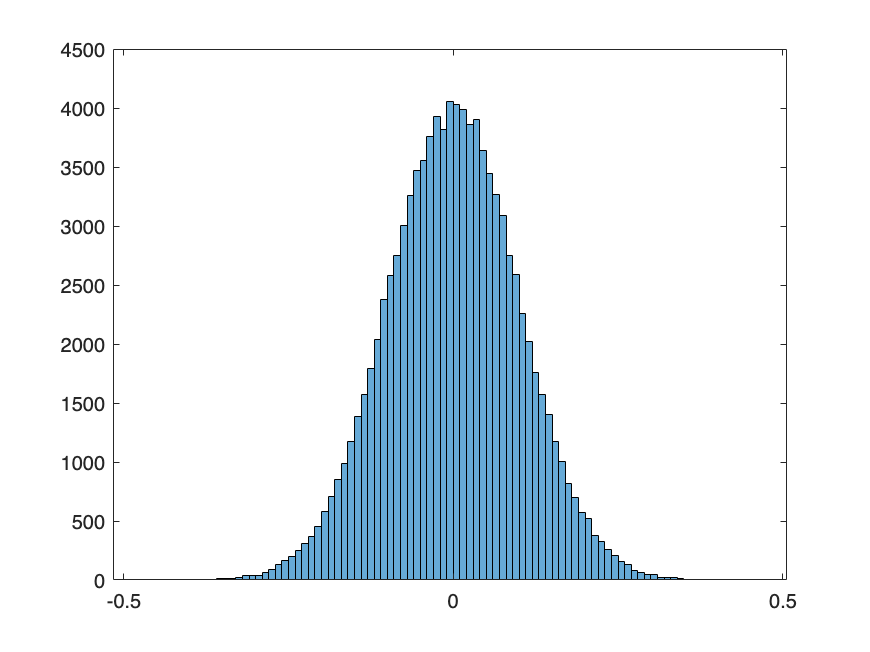

clear
samples = 100000; % does not affect sigma, just precision
% samples = 2;
data = zeros(1, samples);
L = 100;
% signal = sin(exp(linspace(0, 0*pi, L)));
% signal = zeros(1,L);
t = (0:L-1)/L * 1;

data_diff = zeros(1, samples);

stdev_input = 1;
    
for i = 1:samples
    % noisy = signal + stdev_input * randn(1, L);
    % a = trapz(t, noisy);
    data(i) = trapz(t, stdev_input * randn(1, L));
end

close all
hold off
% figure()
histogram(data)

% hold on

% mean(data)

std(data)

ans = 0.0995


predicted = sqrt(L)*(t(end)-t(end-1)) * stdev_input

predicted = 0.1000


predicted2 = stdev_input / sqrt(L) % doesnt factor in time interval, assumes is 1

predicted2 = 0.1000